%{
ES115 emperature Regulation System (Electrical / Biomedical)
 originally from MATLAB Module 2 project bank.pdf - 02/02/2026
Author: Gracy Sylvestre
Version: 2.0
Date: 2026-04-24
State the problem (Purpose):
Use of threshold and hysteresis logic to model a temperature controlled
system.

Describe input values (Knowns)and required output (Unknowns) 
    Input:
       - user input (control mode, initial temp, ambient temp, simulation
       time)
      - heat and cool rate
      - time vector
      - control threshold
        
    Output:
        - plotted results of the system of the system 
       - average, min, and max temp
       - system explanations
     
  Engineering Workflow and Algarithems:
    - build algorithmic model
    - simulation loop
    - Test answers and evaluate results 

MATLAB tools/functions:
    - MATLAB vectors and arrays
    - plots, logic structure and loops 
    - user input
    - documentation. 

%}

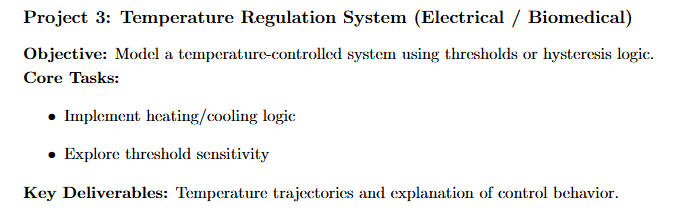

clear; clc; close all;   % Clear workspace

## User Input


 % create user input
control = input("Choose control mode (1 = Threshold, 2 = Hysteresis): "); % Control type selection

Ti = input("Enter initial temperature (°C): "); % systems beginning temp

Ta = input("Enter ambient temperature (°C): "); % Environmental temperature

tend = input("Enter simulation time (seconds): "); % total simulation time

%default input setting

if isempty(control) % If no mode selected
    control = 2; % hysteresis control is default choice
end

if isempty(Ti) % If no initial temperature selected
    Ti = 20; % Default initial temperature
end

if isempty(Ta) % If no ambient temperature selected
    Ta = 25; % Default ambient temperature
end

if isempty(tend) % If no time selected
    tend = 200; % Default simulation time
end

%TIME SETTINGS 
tstep = 1; % size of time step 

N = tend / tstep; % # of simulation steps

% praremeters of the system

Hrate = 0.8; % Heating rate (temperature increase per step)

Crate = 1.0; % Cooling rate (temperature decrease per step)

Tset = 50; % Single threshold setpoint

Hlow = 48; % Lower region for hysteresis control

Hhigh = 52; % Upper region for hysteresis control

%define variables

T = zeros(1, N); %  temperature array for speed

heater = zeros(1, N); % Heater ON/OFF state array

cooler = zeros(1, N); % Cooler ON/OFF state array

T(1) = Ti; % Set initial temperature

%Loop for simulation

for a = 2:N % Loop over each time step
    
    
    if control == 1           % If using simple threshold control
        
        if T(a-1) < Tset    % If temperature below set point
            heater(a) = 1; % Turn heater ON
            cooler(a) = 0; % Turn cooler OFF
        else % If above set point
            heater(a) = 0; % Turn heater OFF
            cooler(a) = 1; % Turn cooler ON
        end
        
    else % If using hysteresis control
        
        if T(a-1) < Hlow % Below lower threshold
            heater(a) = 1; % Turn heater ON
            cooler(a) = 0; % Turn cooler OFF
            
        elseif T(a-1) > Hhigh % Above upper threshold
            heater(a) = 0; % Turn heater OFF
            cooler(a) = 1; % Turn cooler ON
            
        else % Inside hysteresis band
            heater(a) = heater(a-1); % Maintain previous heater state
            cooler(a) = cooler(a-1); % Maintain previous cooler state
        end
        
    end
    
 
    if heater(a) == 1 % If heater is ON
        T(a) = T(a-1) + Hrate; % Increase temperature
        
    elseif cooler(a) == 1 % If cooler is ON
        T(a) = T(a-1) - Crate; % Decrease temperature
        
    else % If neither system is active
        T(a) = T(a-1) + 0.02*(Tamb - T(a-1)); % drift toward ambient
    end
    
end

%VECTOR FOR TIME
time = 0:tstep:(N-1); % Create time axis 

## System results plotted

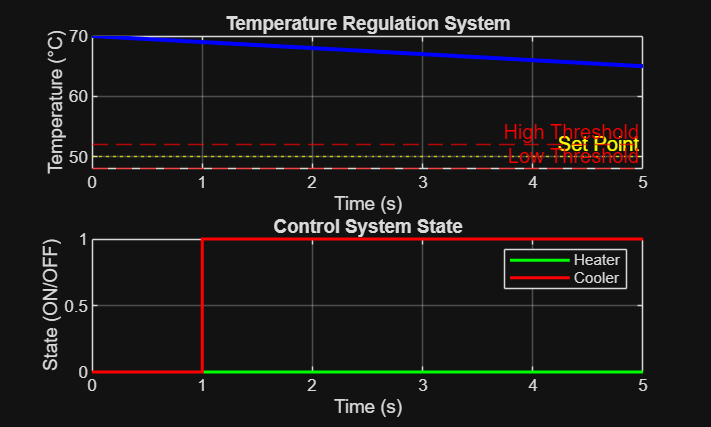


figure;           % new figure window

subplot(2,1,1); % Top plot

plot(time, T, 'b', 'LineWidth', 2); % Plot temperature curve in blue
hold on;                         % prevent line overlay

yline(Tset, ':y', 'Set Point'); % define setpoint line (yellow dotted line)

yline(Hlow, '--r', 'Low Threshold'); % define lower threshold on graph (red dashed line)

yline(Hhigh, '--r', 'High Threshold'); % define upper threshold on graph (red dashed line)

xlabel("Time (s)"); % Label horizontal axis

ylabel("Temperature (°C)"); % Label vertical axis

title("Temperature Regulation System"); % establish graph title

grid on; % Enable grid

subplot(2,1,2); % Bottom plot

stairs(time, heater, 'g', 'LineWidth', 1.5); % plot heater state

hold on; % Hold for second signal

stairs(time, cooler, 'r', 'LineWidth', 1.5); % Cooler state plot

xlabel("Time (s)"); % Label horizontal axis

ylabel("State (ON/OFF)"); % Label vertical axis

legend("Heater","Cooler", 'location', 'northeast'); % Legend in top right corner

title("Control System State"); % Title the graph

grid on; % Enable grid

## System metrics

avgtemp = mean(T); % Compute average temperature

maxtemp = max(T); % Compute maximum temperature

mintemp = min(T); % Compute minimum temperature

fprintf("\n SYSTEM PERFORMANCE \n"); % display header


 SYSTEM PERFORMANCE 



fprintf("Average Temperature: %.2f °C\n", avgtemp); % display average

Average Temperature: 67.50 °C



fprintf("Max Temperature: %.2f °C\n", maxtemp); % display max

Max Temperature: 70.00 °C



fprintf("Min Temperature: %.2f °C\n", mintemp); % display min

Min Temperature: 65.00 °C


## Export data

data = table(time', T', heater', cooler', ... % Create data table
    'VariableNames', {'Time','Temperature','Heater','Cooler'}); % Column names

writetable(data, "tempcontrol.csv"); % Export to CSV

fprintf("\nResults exported to tempcontrol.csv\n"); % Confirm export abd display


Results exported to tempcontrol.csv


## System explanation 

fprintf("\n SYSTEM EXPLANATION \n"); % Section title


 SYSTEM EXPLANATION 



if control == 1 % If threshold control used
    fprintf("Threshold control leads to frequent switching.\n"); % threshold Explanation
else % If hysteresis used
    fprintf("Hysteresis control reduces switching and stabilizes system behavior.\n"); % hysteresis Explanation
end

Threshold control leads to frequent switching.



fprintf("System naturally stabilizes near ambient temperature with control.\n"); % Finishing thought

System naturally stabilizes near ambient temperature with control.


%{
Reflection After Completing the Project:
    - What did you learn?
    - What could be done differently?
    - Rate the project (1 - 10) 
      (1 - represents simple and 10 represents difficult) 
      This rating should reflect the level of complexity and challenge experienced.
      Factors influencing this rating should include the unfamiliarity of concepts,
      the level of critical thinking required,
      and the degree of effort needed to complete the project successfully.
%}